# Importing data into MATLAB

MATLAB can read in a large number of commonly used file types including excel, csv and txt files. MATLAB data files are saved in the '.mat' format. Here we will use the uiimport tool to import a csv dataset. We will also use the 'load' function to load a '.mat' file.

You can use the Meteorite_Landings.csv and Meteorite_Landings.mat files provided in the GitHub repository:

[https://github.com/DUsluel/MATLAB-Beginners-Training](https://github.com/DUsluel/MATLAB-Beginners-Training)

- Make sure that both of the files are in your Current Folder before attemting to import and load them in your workspace

uiimport('Meteorite_Landings.csv',1)

Writing the above function will open a new window showing the data.

By clicking "import selection" on the top right you will command MATLAB to import the data into your workspace.

You should see a variable of type table named "MeteoriteLandings" in your workspace after MATLAB finsihes organizing and importing your data.

load('Meteorite_Landings.mat')

ans = "Aachen"

"Meteorite_Landings.mat" is an already saved MATLAB workspace file. Whenever you press "save" on your MATLAB workspace a ".mat" file will be created saving the current variables on the workspace.

After you enter the above code, you should see a variable of type struct named "continents" on your workspace.

- You can observe both datasets by cliking their names in the Workspace

## Indexing data

Let us look at the name of the first meteorite

- We will use the variable "MeteoriteLandings" of type table in this part

Because we are working with a table we can use both the "dot" notation or indexing.

% Using the dot notation
MeteoriteLandings.name(1)

ans = table
      name  
    ________

    "Aachen"


By using ".name" we have accessed the first column of the table as the first column is titled name. This is similar to a struct. But by putting (1) we have adressed the first row to obtain the name of the first meteor.

We could also index both the column and the row using numbers:

% using numerical index
MeteoriteLandings(1,1)

ans = "Aarhus"

In this case we used the notation (1,1) where the first value is the row index and the second valu is the column index. This is similar to a matrix.

However you can see that the outputs differ slightly. Where the first example has outputed a string and the second example has outputted a table element with only one column and one row.

Look at second meteorite

MeteoriteLandings.name(2) %using dot notation

ans = table
      name  
    ________

    "Aarhus"


MeteoriteLandings(2,1) % using numerical index

Display the names of the first 5 meteorites

MeteoriteLandings.name(1:5) %using dot notation

ans = 5×1 string array
    "Aachen"
    "Aarhus"
    "Abee"
    "Acapulco"
    "Achiras"


MeteoriteLandings(1:5,1) % using numerical index

ans = 5×1 table
       name   
    __________

    "Aachen"  
    "Aarhus"  
    "Abee"    
    "Acapulco"
    "Achiras" 


It is seen that by using a colon ":" it is possible to describe a range. Here the row index is given as "1:5" meaning to take every row in the first five rows.

If we wanted to look at the name of the every second meteorite:

MeteoriteLandings.name(1:2:5) %using dot notation

ans = 3×1 string array
    "Aachen"
    "Abee"
    "Achiras"


MeteoriteLandings(1:2:5,1) % using numerical index

ans = 3×1 table
      name   
    _________

    "Aachen" 
    "Abee"   
    "Achiras"


In this case, the index term has become "(1:2:5)" which describes getting every second row in the first five rows. Hence, the 1st, 3rd and 5th rows are displayed.

e.g. (10:20:100) would define getting every 20th element from the elements between 10 and 100. 10th, 30th, 50th, 70th, 90th.

**Try it yourself:**

Try to obtain the values written in the comments below using the "dot" notation and numerical indexes

% Mass of meteorite 1


% Mass of meteorite 2


% Display the mass of the first 5 meteorites


% Mass of every second meteorite


Let us look at a matrix. The latitude, longitude and mass of the first meteor.

% Using dot notation
MeteoriteLandings.GeoLocation(1) 

ans = "(50.775000, 6.083330)"

MeteoriteLandings.massg(1)

ans = 21

% Using numerical index
MeteoriteLandings(1,10) % The latitude and longitude values are contained in 10th column named GeoLocation

ans = table
          GeoLocation      
    _______________________

    "(50.775000, 6.083330)"


MeteoriteLandings(1,5) % The mass values are contained in 5th column named massg

ans = table
    massg
    _____

    21   


% first row refers to the first meteorite data

## Challenge 2

Create a square matrix in your workspace that is filled with random numbers.

A square matrix has the equal number of rows and columns

HINT: randi([a b],Nrows,Ncols), creates a random matrix filled with numbers between a and b, and of the size specified by Nrows x Ncols

randi([-10 10],2,3) is a matrix with 2 rows, and 3 columns, containing numbers between -10 and 10

Try it out! 

random_matrix = randi([-10 10],3,3) % Square matrix with 3 rows and 3 columns with random values ranging from -10 to 10

random_matrix =     -5    -2    -7
     2    -4    -2
   -10    -7    -9


**PART ONE**

Now can you use indexing to:

- Select the number in the top left corner

- Select the number in the bottom right corner\

- Select the entire top row

- Select the entire middle column

% 1. Select the number in the top left corner
random_matrix(1,1) % 1st row, 1st column

ans = -5


% 2. Select the number in the bottom right corner
random_matrix(3,3) % 3rd row, 3rd column

ans = -9

To obtain the last element in a row or column "end" can also be used regardless of the matrix size

% 2. Select the number in the bottom right corner
random_matrix(end,end) % last row, last column

ans = -9


% 3. Select the entire top row
random_matrix(1,1:3) % 1st row, columns 1 to 3

ans =     -5    -2    -7


To select all the columns in a row or all the rows in a columns a colon ":" can be used instead of a numerical index

% 3. Select the entire top row
random_matrix(1,:) % 1st row, all columns

ans =     -5    -2    -7



% 4. Select the entire middle column
random_matrix(1:3,2) % rows 1 to 3, 2nd column

ans =     -2
    -4
    -7


% OR
random_matrix(:,2) % all rows, middle (2nd) column

ans =     -2
    -4
    -7


**PART TWO**

MATLAB is most useful for dealing with numbers, so we haven't talked much about strings (vectors of letters).

- Create a string with your celebrity name in it and call it my_name (HINT your celebrity name is your middle name followed by the name of the first street you lived on).

my_name = 'DorukAnt' % My name is Doruk and the first street I lived in was Ant street

my_name = 'DorukAnt'

- Create a new variable called my_code_name, which contains only every second letter of my_name (HINT: remember how to index in steps?)

my_code_name = my_name(1:2:end) % you can index a character array like any vector, every index is a character

my_code_name = 'Drkn'

- Create your own code (for an example see what fliplr does to my_name)

example_code_name = fliplr(my_name)

example_code_name = 'tnAkuroD'

## Analysing Data

Finding the mean mass of the first 10 meteors.

Use the "mean" function. The function takes any amount of numbers as input and calculates the mean of all the numbers. 

*mean_output = mean(input_values)*

mean_first10meteormass = mean(MeteoriteLandings.massg(1:10))

mean_first10meteormass = 1.4864e+04

Find the minimum, maximum and standard deviation

min_first10meteormass = min(MeteoriteLandings.massg(1:10))

min_first10meteormass = 21

max_first10meteormass = max(MeteoriteLandings.massg(1:10))

max_first10meteormass = 107000

std_first10meteormass = std(MeteoriteLandings.massg(1:10))

std_first10meteormass = 3.3612e+04

## Challenge 3

In this challenge we are going to be analysing some of the meteorite data.                       

- Find the latitude and longitude of the first meteorite to land.

- Find the northern (maximum latitude),southern (minimum latitude), eastern (maximum longitude) and western (minimum longitude) most meteorites. 

## Plotting Data

In MATLAB, we can plot data by using the plot function or the plots tab!

The plot function

Plotting the masses of the first 10 meteors.

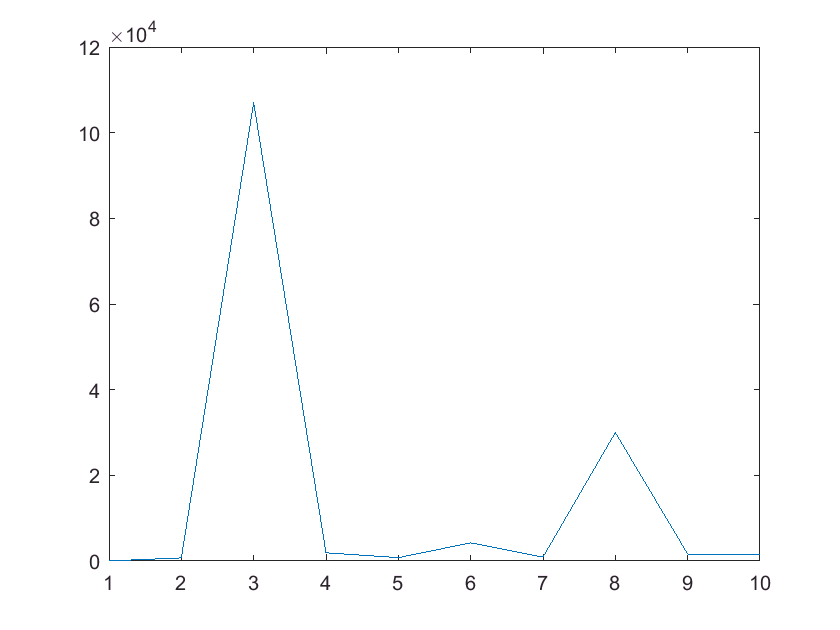

plot(MeteoriteLandings.massg(1:10)) % for more information on plot type "help plot" on the command window

Scatter plot

Scatter plot the lattitude and longitude of the first 10 meteorite landings

- In the MeteoriteLandings table the lattitude is contained as reclat and the longitude is contained under the name reclong

- We will place the longitude values on the x axis and latitude values on the y axis

figure_handle = scatter(MeteoriteLandings.reclong(1:10),MeteoriteLandings.reclat(1:10))

figure_handle =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [6.0833 10.2333 -113 -99.9000 -64.9500 71.8000 95.1667 0.6167 -65.2333 -64.5500]
              YData: [50.7750 56.1833 54.2167 16.8833 -33.1667 32.1000 44.8333 44.2167 -31.6000 -30.8667]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


For each of the first 10 meteorites one point is plotted on the figure at the corresponding longitude (x) and lattitude values 

Editing plot properties

You can modify plot properties by:

- Going to "Edit->Figure Properties" tab on the figure window (explore this option)

- Using general scripting to change figure properties

- Using the handle, which is created by equating the plot to a variable in the code as shown with the scatter plot script above

% Using general scripting examples
xlabel('Longitude') % Give titles to your axis
ylabel('Latitude')
xlim([-200 200]) % Set the limits of the values you want to be presented in your figure
ylim([30 80])
title('Meteorite Locations (longitude vs latitude)') % Give a title to your figure

Much more can be discovered from the MATLAB documentation on Mathworks.com

or by typing "help figure" into the command window

% Usingthe figure handles
figure_handle.Marker = '*'

figure_handle =   Scatter with properties:

             Marker: '*'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [6.0833 10.2333 -113 -99.9000 -64.9500 71.8000 95.1667 0.6167 -65.2333 -64.5500]
              YData: [50.7750 56.1833 54.2167 16.8833 -33.1667 32.1000 44.8333 44.2167 -31.6000 -30.8667]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


figure_handle.MarkerEdgeColor = 'red' %or

figure_handle =   Scatter with properties:

             Marker: '*'
    MarkerEdgeColor: [1 0 0]
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [6.0833 10.2333 -113 -99.9000 -64.9500 71.8000 95.1667 0.6167 -65.2333 -64.5500]
              YData: [50.7750 56.1833 54.2167 16.8833 -33.1667 32.1000 44.8333 44.2167 -31.6000 -30.8667]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


figure_handle.MarkerEdgeColor = 'g' % there are preset color values such as b: blue, k: black, r: red in MATLAB

figure_handle =   Scatter with properties:

             Marker: '*'
    MarkerEdgeColor: [0 1 0]
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [6.0833 10.2333 -113 -99.9000 -64.9500 71.8000 95.1667 0.6167 -65.2333 -64.5500]
              YData: [50.7750 56.1833 54.2167 16.8833 -33.1667 32.1000 44.8333 44.2167 -31.6000 -30.8667]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


Saving to file: Use the save file

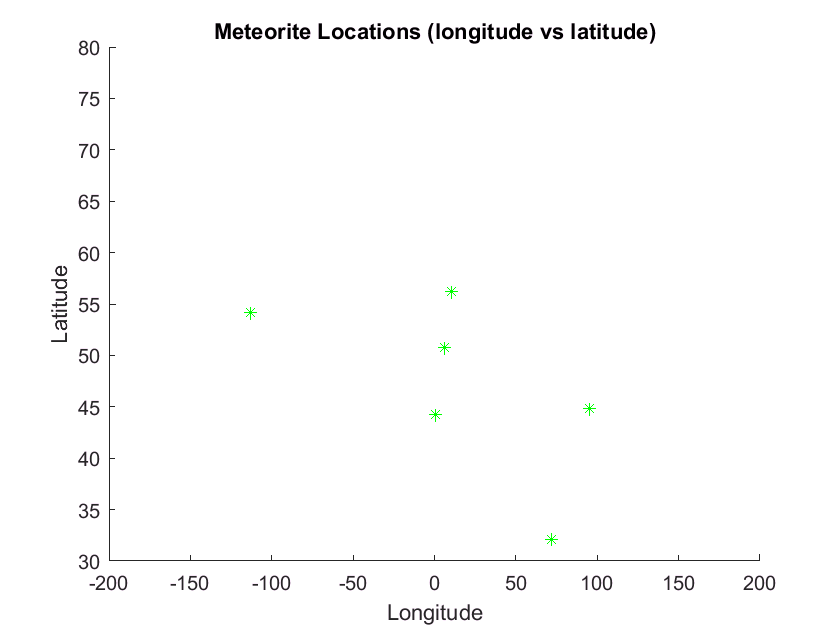

print('name', '-dpng');
savefig();

saveas(figure_handle,'scatter_longlat_example')

## **Challenge 4**

**Do your WORST!**

The aim of this challenge is to make the worst data visualisation possible.

Make a plot of the masses of the first 100 meteorites. You can use any of the options on the plots tab.

Make the ylim between 0 and 100000.

Edit the plot to make it the ugliest ever. TWEET the results @ResPlat. You can also tag MATLAB using the @MATLAB tag.